syms t

p = [t^5 t^4 t^3 t^2 t 1];

alpha = eval(inv(int(p'*p,0,pi))*int(p'*sin(t),0,pi))

alpha =    -0.0000
    0.0372
   -0.2338
    0.0545
    0.9826
    0.0013



t_vec = linspace(0,1.5*pi,1e6)

t_vec =          0    0.0047    0.0094    0.0141    0.0188    0.0236    0.0283    0.0330    0.0377    0.0424    0.0471    0.0518    0.0565    0.0613    0.0660    0.0707    0.0754    0.0801    0.0848    0.0895    0.0942    0.0990    0.1037    0.1084    0.1131    0.1178    0.1225    0.1272    0.1319    0.1367    0.1414    0.1461    0.1508    0.1555    0.1602    0.1649    0.1696    0.1744    0.1791    0.1838    0.1885    0.1932    0.1979    0.2026    0.2073    0.2121    0.2168    0.2215    0.2262    0.2309


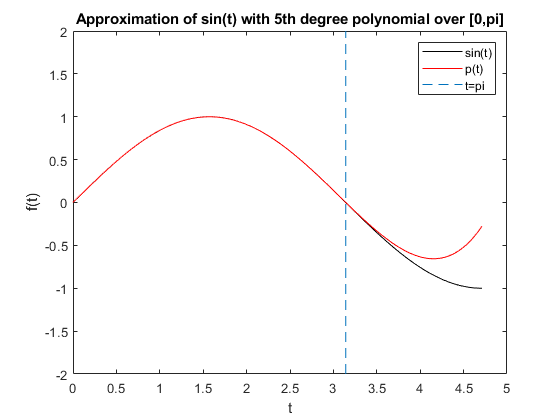


orig = sin(t_vec);
approx = [t_vec.^5' t_vec.^4' t_vec.^3' t_vec.^2' t_vec' t_vec.^0']*alpha;
figure
plot(t_vec,orig,'k-')
hold on
plot(t_vec,approx, 'r')
plot([pi,pi],[-2,2],'--')
legend('sin(t)','p(t)','t=pi')
xlabel('t')
ylabel('f(t)')
title('Approximation of sin(t) with 5th degree polynomial over [0,pi]')

t = linspace(0,pi,10000);
y = sin(t)';
T = [t.^5;t.^4;t.^3;t.^2;t;t.^0]'

T =          0         0         0         0         0    1.0000
    0.0000    0.0000    0.0000    0.0000    0.0003    1.0000
    0.0000    0.0000    0.0000    0.0000    0.0006    1.0000
    0.0000    0.0000    0.0000    0.0000    0.0009    1.0000
    0.0000    0.0000    0.0000    0.0000    0.0013    1.0000
    0.0000    0.0000    0.0000    0.0000    0.0016    1.0000
    0.0000    0.0000    0.0000    0.0000    0.0019    1.0000
    0.0000    0.0000    0.0000    0.0000    0.0022    1.0000
    0.0000    0.0000    0.0000    0.0000    0.0025    1.0000
    0.0000    0.0000    0.0000    0.0000    0.0028    1.0000



alpha = inv(T'*T)*T'*y

alpha =     0.0000
    0.0372
   -0.2338
    0.0545
    0.9826
    0.0013


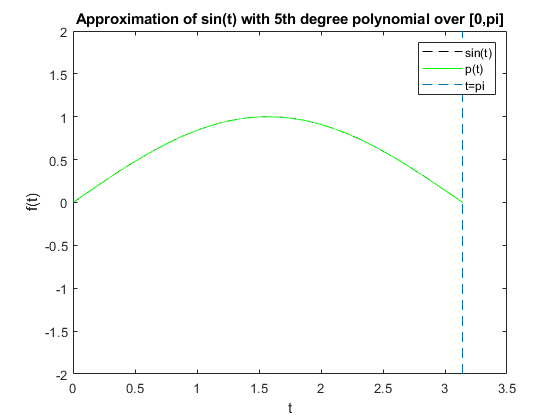


yhat = T*alpha;
figure
plot(t,y,'k--')
hold on
plot(t,yhat, 'g')
plot([pi,pi],[-2,2],'--')
legend('sin(t)','p(t)','t=pi')
xlabel('t')
ylabel('f(t)')
title('Approximation of sin(t) with 5th degree polynomial over [0,pi]')

[A,B,C,D] = rmodel(40)

A =    -0.9563   -1.0506    0.4175   -0.9251   -0.5821   -2.2660   -0.9075   -0.2696   -0.7456   -1.6574    0.4373   -0.6442   -0.5131   -1.8530    0.6202   -0.1917   -0.0743   -0.7685   -0.0142   -1.4883    0.3364    0.7203   -0.7052   -0.3986    0.1095    1.7944   -0.0758    1.4750    0.2763    0.9314    0.2788   -0.6957   -0.7747    0.1059    3.1907    0.1120    1.1422   -0.2660   -1.1405    0.0605
    1.0143   -2.2060   -0.9032   -0.5562   -0.8988   -1.8404   -1.1663   -2.2442   -0.8446   -1.5214   -0.5831    0.1654    0.0585   -0.8183    0.1812   -0.7463    0.3367    0.7572   -1.1901   -0.4466   -0.2610   -0.6747    0.7976    2.0454    1.1962    0.7875   -0.5229    2.5662   -0.9798   -0.5262    1.0473    0.7686    0.0456    0.6030    1.0734    0.1233    0.6617   -0.0054    0.8245   -1.2382
   -0.7358   -0.3723   -1.6511   -0.4731    0.0007    0.9556    0.1296    0.7801   -0.0617   -0.7095   -0.1050    0.4056   -0.1967   -0.0532   -0.0913   -0.5096    0.0768    1.2820   -0.1321   -

B =     0.8294
    0.1556
    0.0837
    0.3746
    2.6532
    0.3327
    0.1408
    1.5778
    0.0895
   -0.6730


C =     1.8233   -1.2084         0         0   -1.1492         0    0.6464   -1.3892   -1.3407         0    0.0017    0.3797   -0.9013         0    0.3069    0.1675    1.7881         0         0    0.8322    0.9481   -1.9737   -0.3919         0   -0.0160         0    0.4448    1.1409         0         0    0.9456         0   -1.3246         0         0         0   -2.1079   -0.5498    0.0943   -0.0382


D = 1.8829

n = 12000

n = 12000

t = linspace(0,10,n);
y = exp(-t).*cos(2*t)+exp(-t/2).*sin(t);
y = y';
T = zeros(n,40);
for i = 1:n
    T(i,:) = C*expm(A*t(i));
end

xhat = pinv(T)*y

xhat = 	1.0e+05 *

   -0.0976
    0.5172
   -0.7888
   -0.4081
   -1.6227
   -0.1827
    1.7015
    2.2376
    0.9869
    0.3444


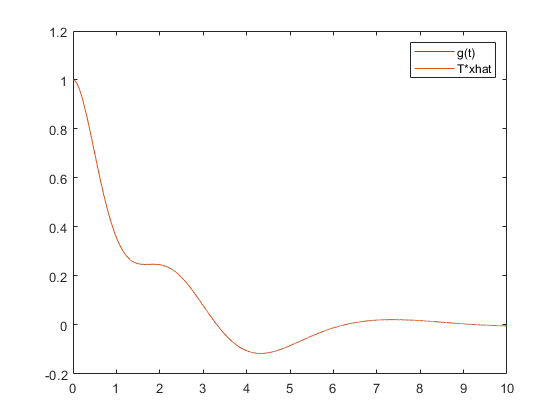

yhat = T*xhat;
figure
plot(t,y)
hold on
plot(t, yhat)
legend('g(t)','T*xhat')